clear

addpath(genpath("Support Functions"));

settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;


## System Definition

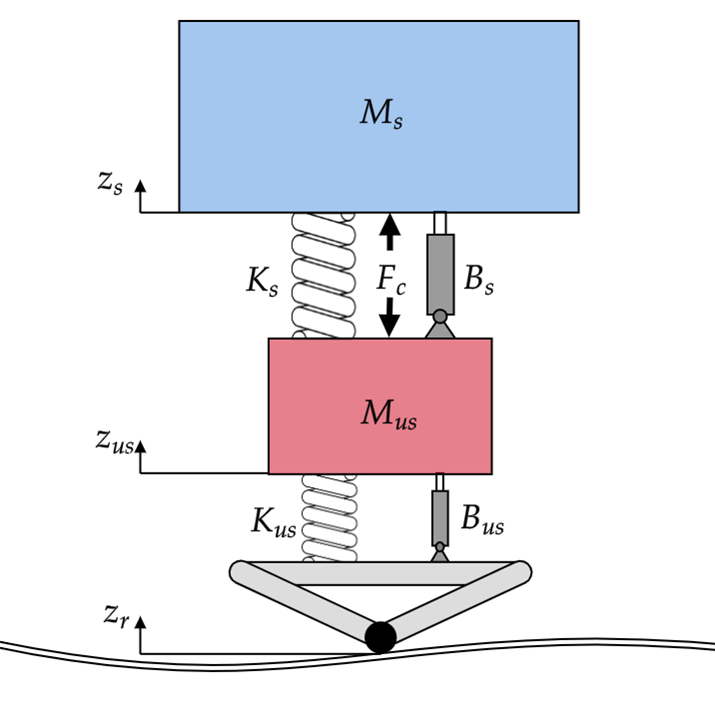

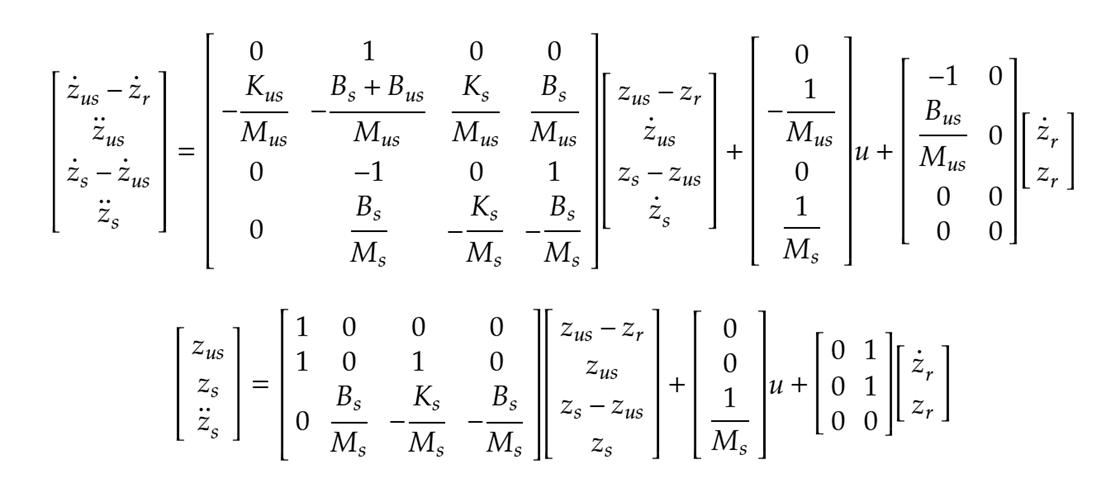

Task-1: Define the quarter car model dynamics


% System dimensions
nx = 4; % Number of states
nu = 1; % Number of inputs (controllable)
nd = 2; % Number of disturbances
ny = 3; % Number of outputs

% Model parameters
Ks = 900;   % Suspension Stiffness (N/m) 
Kus = 1250;  % Tire stiffness (N/m)
Ms = 2.45;  % Sprung Mass (kg) 
Mus = 1;     % Unsprung Mass (kg)
Bs = 7.5;   % Suspension Inherent Damping coefficient (sec/m)
Bus = 5;    % Tire Inhenrent Damping coefficient (sec/m)

% Continuous-time state-space model
% x1 = z_us-z_r (length of tire spring)
% x2 = z_us_dot (velocity of unsprung mass)
% x3 = z_s-z_us (length of suspension spring)
% x4 = z_s_dot (velocity of sprung mass)
% u1 = F_c (active suspension force)
% d1 = z_r_dot (rate of change of road height)
% d2 = z_r (road height)
% y1 = z_s-z_us (length of suspension spring)
% y3 = zs_dotdot (acceleration of sprung mass)

%% Define Your Model Here
Ac = ; % State Matrix
Bc = ; % Input Matrix
Vc = ; % Distrubance
C = ; % Output
D = ; % Feedthrough
W = ; % Output Distrubance
% LTI system 
sys_c = ss(Ac,[Bc Vc],C,[D W]);


## Constraints


% Maximum tire deflection +/- 0.01 meters
% Maximum unsprung mass velocity is +/- 1 m/s
% Maximum suspension deflection +/- 0.03 meters
% Maximum unsprung mass velocity is +/- 1 m/s
% Maximum force is +/- 30 N
% Maximum change in road profile velocity +/- 0.5 meters/second
% Maximum change in road height +/- 0.02 meters
bounds.x_ub = [0.01; 1; 0.03; 1];
bounds.x_lb = -bounds.x_ub;
bounds.u_ub = 30;
bounds.u_lb = -bounds.u_ub;
bounds.d_ub = [0.5; 0.02];
bounds.d_lb = -bounds.d_ub;

X_set = Polyhedron('lb',bounds.x_lb,'ub',bounds.x_ub);
U_set = Polyhedron('lb',bounds.u_lb,'ub',bounds.u_ub);
D_set = Polyhedron('lb',bounds.d_lb,'ub',bounds.d_ub);


## Open-loop Simulation (no active suspension force)

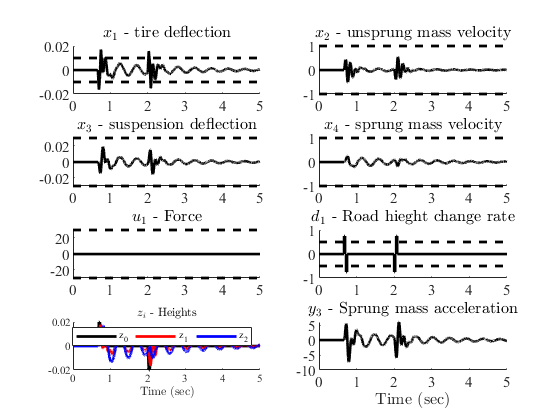


tmax = 5;                               % simulation time length (must be less than 10 - will run out of road)
scale = 1;                              % Scaling of road height
x0 = zeros(nx,1);                       % initial condition
v = 15;                                 % vehicle velocity (m/s) (will change the simulation time step)

load roadBumpHole                       % road profile data (one bump and one hole)

dx = road_x(2) - road_x(1);             % spacial step for input data
dt = dx/v;                              % simulation time step
t = 0:dt:tmax;                          % simulation time
z0 = road_z(1:tmax*v/dx+1)*scale;       % road height
z0dot = [0 diff(z0)/dt];            	% road profile velocity
pos = v*t;                              % position along the road
sys_d = c2d(sys_c,dt);                  % Discrete-time state-space model for simulation

% Collect inputs/disturbances
u_OL = zeros(length(t),nu+nd);          % Zero force
u_OL(:,2) = z0dot;                      % Rate of change of road height
u_OL(:,3) = z0;                         % Road height

% Simulate open-loop system
[y_OL,~,x_OL] = lsim(sys_d,u_OL,t,x0);
% Plot all simulation data
plotActiveSuspension(t,u_OL,x_OL,y_OL,bounds)

% Animate simulation data (can comment out if you dont want to animate)
%animateActiveSuspension(t,u_OL,y_OL,road_x,road_z,pos,scale)

## PD Controller Design

Task-2: Design PD gains to stabilize $z_s$

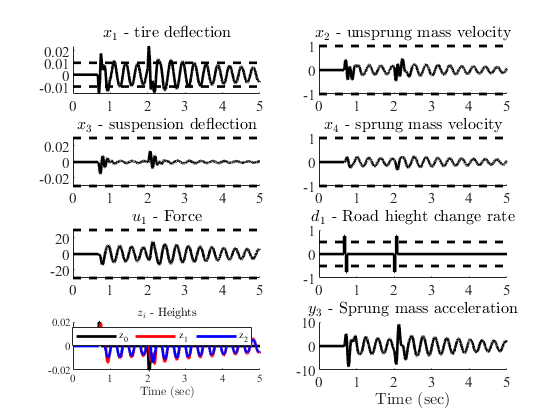

% Design the PD Gains 
Kp = ;
Kd = ;

tmax = 5;                               % simulation time length (must be less than 10 - will run out of road)
scale = 1;                              % Scaling of road height
x0 = zeros(nx,1);                       % initial condition
v = 15;                                 % vehicle velocity (m/s) (will change the simulation time step)

load roadBumpHole                       % road profile data (one bump and one hole)

dx = road_x(2) - road_x(1);             % spacial step for input data
dt = dx/v;                              % simulation time step
t = 0:dt:tmax;                          % simulation time
z0 = road_z(1:tmax*v/dx+1)*scale;       % road height
z0dot = [0 diff(z0)/dt];            	% road profile velocity
pos = v*t;                              % position along the road
sys_d = c2d(sys_c,dt);                  % Discrete-time state-space model for simulation

% Collect inputs/disturbances
u_OL = zeros(length(t),nu+nd);          % Zero force
u_OL(:,2) = z0dot;                      % Rate of change of road height
u_OL(:,3) = z0;                         % Road height


% PD Feedback Loop
Ki = 0; 
pD_C = pid(Kp,Ki,Kd,dt);

% Simulate open-loop system

error = 0;
u_L = [0];
x_OL = [x0'];
y_OL = [0 0 0];

for i = 1:size(t,2)-1
    
    [u,~,~] = lsim(pD_C,[error; error],[t(i) t(i+1)],0);

    [y,~,x] = lsim(sys_d,[u(1) z0dot(i) z0(i); u(1) z0dot(i) z0(i)],[t(i); t(i+1)],x_OL(i,:));
    error = y(3);
    
    u_L = [u_L; u(1)];
    x_OL = [x_OL; x(2,:)];
    y_OL = [y_OL; y(2,:)];   
end

u_OL = [u_L u_OL(:,2:3)];

% Plot all simulation data
plotActiveSuspension(t,u_OL,x_OL,y_OL,bounds)

## MPC Controller Design

Task-3: Define the Cost Function weights and prediction horizon for the MPC optimization problem


% MPC cost function matrices 
Q = ; % DESIGN THIS
R = ; % DESIGN THIS
N = 50;

% Discrete-time step for MPC (must be an integer multiple of dt)
dt_MPC = 0.02;
% Resample discrete-time model with MPC time step
sys_MPC = d2d(sys_d, dt_MPC);

% Optimization variables (Choose your Yalmip sdpvar varaibles)
x_ = sdpvar(repmat(4,1,N+1), repmat(1,1,N+1));
u_ = sdpvar(repmat(1,1,N), repmat(1,1,N));
d_ = sdpvar(repmat(1,1,N), repmat(1,1,N));
s = sdpvar(1,1);

constraints = [];
objective = 0;
for k = 1:N
    objective = objective + x_{k}'*Q*x_{k} + u_{k}'*R*u_{k} + 1000*s^2;
    constraints = [constraints, x_{k+1} == sys_MPC.A*x_{k} + sys_MPC.B(:,1)*u_{k} + sys_MPC.B(:,2)*d_{k}, X_set.A*x_{k} <= X_set.b + s, U_set.A*u_{k} <= U_set.b, s >= 0];
end

controller = optimizer(constraints,objective,sdpsettings('solver','quadprog'),{x_{1},[d_{:}]},{[u_{1}]});



## Closed-loop MPC Simulation


x_sim = [x0];           % Store states
u_sim = [];             % Store inputs
y_sim = [];             % Store outputs
s_sim = [];             % Store slack (if you use it)
errors = [];            % Store diagnostics
tCalcs = [];            % Store MPC computation times
z0dot2 = [z0dot z0dot]; % Extend for prediction horizon
% Choose what the MPC controller knows (0 - no disturbance, 1 - current
% distrubance, 2 - full disturbance preview)
dFlag = 2;
for i = 1:length(t)-1
    % Call controller every dt_MPC seconds
    if mod(i-1,dt_MPC/dt) < eps 
        if dFlag == 0
            d_MPC = mat2cell(zeros(1,N),1,ones(1,N));
        elseif dFlag == 1
            d_MPC = mat2cell(repmat(z0dot2(i+1),1,N),1,ones(1,N));
        elseif dFlag == 2
            d_MPC = mat2cell(z0dot2(i+1:dt_MPC/dt:i+dt_MPC/dt*N),1,ones(1,N));
        end
        % Modify this section as needed depending on your inputs/outputs
        % Define controller inputs
        inputs = {x_sim(:,end),cell2mat(d_MPC)}; 
        tic
        [out,diagnostics] = controller{inputs};
        tCalc = toc;
        % Unpack controller outputs with optimal input at first time step
        % denoted by the variable u (to be used below)
        u = out;
        tCalcs = [tCalcs tCalc];
        errors = [errors, diagnostics];
    end
    % Update model every dt seconds
    u_sim = [u_sim u];
    y_sim = [y_sim sys_d.C*x_sim(:,end) + sys_d.D(:,1)*u + sys_d.D(:,2:3)*[z0dot(i+1); z0(i+1)]];
    x_sim = [x_sim sys_d.A*x_sim(:,end) + sys_d.B(:,1)*u + sys_d.B(:,2:3)*[z0dot(i+1); z0(i+1)]];
end
% Display diagnostics (0 = no errors)
max(errors)

ans = 0

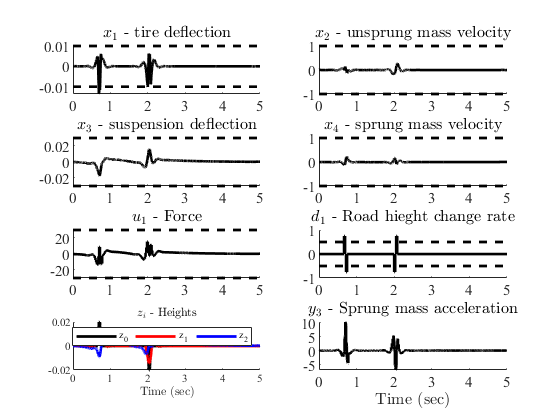

% Rotate for plotting
x_sim = x_sim';
u_sim = u_sim';
u_sim = [u_sim;u_sim(end)];
u_sim = [u_sim z0dot' z0'];
y_sim = y_sim';
y_sim = [y_sim;y_sim(end,:)];

% Plot all simulation data
plotActiveSuspension(t,u_sim,x_sim,y_sim,bounds)

% Animate simulation data (can comment out if you dont want to animate)
%animateActiveSuspension(t,u_sim,y_sim,road_x,road_z,pos,scale)